## Reading P3 Data

load('results_BrainBonus2_P3.mat')
recollect_data

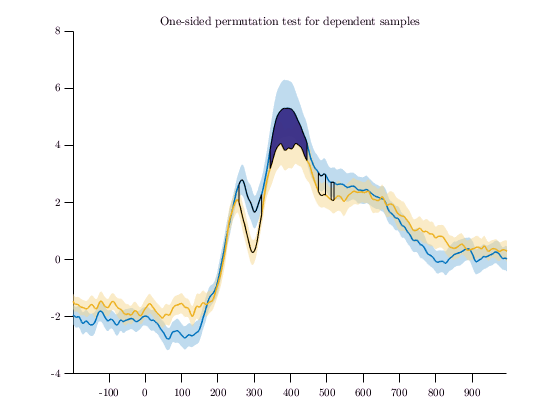

Cluster 1: time points 140 to 166, t-sum = 76.0178, p-value = 0.020098.
Cluster 2: time points 118 to 134, t-sum = 42.6125, p-value = 0.0919908.
Cluster 3: time points 174 to 179, t-sum = 11.9277, p-value = 0.544446.
Cluster 4: time points 183 to 185, t-sum = 5.80484, p-value = 0.727927.


wavelet_phases_r = zeros([length(freqs), length(times), max(condition_positions), length(results)]);
for freq_ind = 1:length(freqs)
    for subj_ind = 1:length(results)
        for cond_ind = 1:size(theta_phases_condition,2)
            wavelet_phases_r(freq_ind, :,cond_ind,subj_ind) = circ_r(squeeze(results{subj_ind}.phases(1,freq_ind,:,results{subj_ind}.condition_positions == cond_ind)),[],[],2);
        end
    end
end


freq_min = 4.5;
freq_max = 8;
theta_phases_r = zeros([length(times), max(condition_positions), length(results)]);
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);

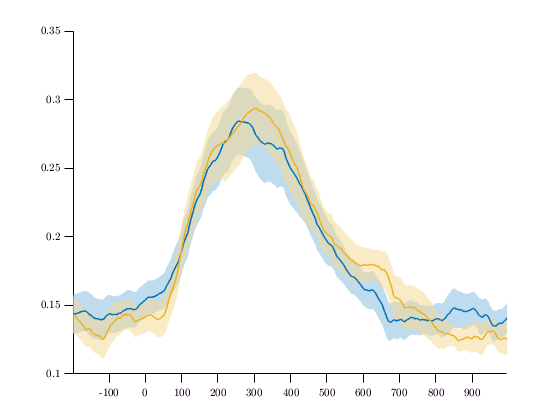

No significant clusters found.


    for cond_ind = 1:size(theta_phases_condition,2)
        theta_phases_r(:,cond_ind,subj_ind) = circ_r(theta_phases_subject(:,results{subj_ind}.condition_positions == cond_ind),[],[],2);
   end

end

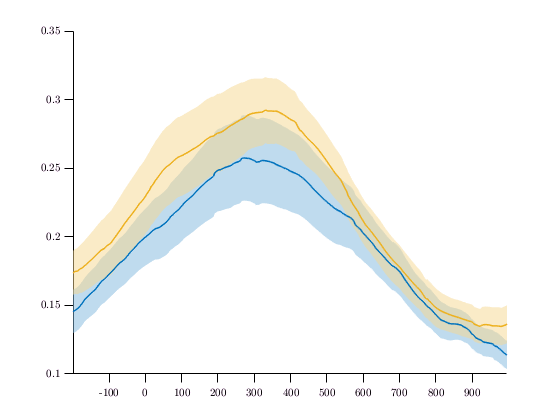

No significant clusters found.


figure;
inds1=[2,4];

inds2=[1,3];
show_perm_results(total_erps, inds1, inds2, u, t)

Cluster 1: time points 1 to 9183, t-sum = 2389.61, p-value = 0.00249975.


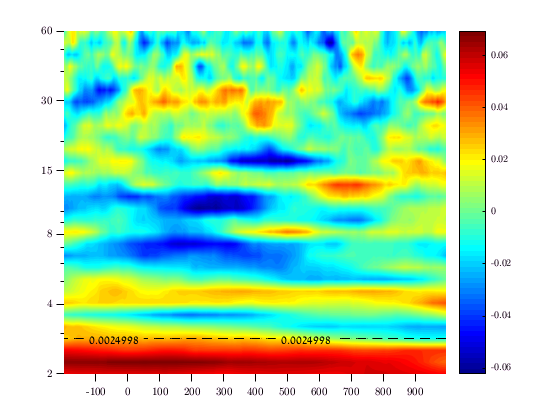

figure;

show_perm_results(theta_phases_r, inds1, inds2, u, t)

figure;
show_perm_results(wavelet_phases_r(11,:,:,:), inds1, inds2, u, t, freqs)

figure;

h = 1

p = 7.0586e-04

show_perm_results(wavelet_phases_r, inds1, inds2, u, t, freqs)

h = 0

p = 0.3405

v = 350 < times & times < 450;
% freq 11 = 6.5Hz
[h,p] = ttest(mean(P3_means([1,2],:)), mean(P3_means([3,4],:)))
[h,p] = ttest(mean(mean(wavelet_phases_r(11,v,[1,2],:),2),3), mean(mean(wavelet_phases_r(11,v,[3,4],:),2),3))